**COT 5930 DIGITAL IMAGE PROCESSING**

**DR. HARI KALVA** 

**SPRING 2024**

**IAN MORGAN-GRAHAM**

**MATLAB ASSIGNMENT 1 - EXPANSION OF IMAGE TRAINING DATA SET THROUGH IMAGE PROCESSING/TRANSFORMATION**

**TABLE OF CONTENTS**

**SECTION 1: TASK A. READ IMAGES INTO A WORKSPACE VARIABLE**

**SECTION 2: TASK B. DISPLAY THE IMAGES**

**SECTION 3: TASK C. APPLY AN IMAGE PROCESSING FILTER/EFFECT OF YOUR CHOICE TO THE IMAGES**

**SECTION 4: TASK D. DISPLAY THE RESULTS**

**SECTION 5: TASK E. SAVE THE RESULTING IMAGES TO .PNG FILE FORMAT**

**SECTION 6: FUNCTIONS**

**SECTION 7: REFERENCES**

Set Up: 

1.) Load this file, 'Assignment1.mlx', the needed image files (betta.jpeg, gourami.jpeg, redtail_shark.jpeg, tiger_barb.jpeg ), and the folder "Output Images" into the same folder and make a note of the directory path leading to this contents folder.

2.) Determine the present working directory with the "pwd" command  in Matlab Command Window. Note the ans = 'result' where 'result' is the current working directory.

3.) In the Matlab Command Window, enter "cd" followed by the directory path leading to the contents folder noted in 2.). This will change the current working directory to the directory path leading to the contents folder. 

4.) Verify the new present working directory change by retyping "pwd" in the Matlab Command Window.

**SECTION 1: TASK A. READ IMAGES INTO A WORKSPACE VARIABLE.                   ****TABLE OF CONTENTS**   

Four images will be read into the workspace for four common aquarium fish species. These four species are part of a larger image collection that will be used for later image classification. This assignment will be used to create a means of expanding/refining the training image data set by creating slight variations (image size standardization, image flipping, image rotation) in the original images. 

1-- Siamese Fighting Fish (*Betta splendens*) The crowntail variety of the fish was selected due to its more dramatic fin structure

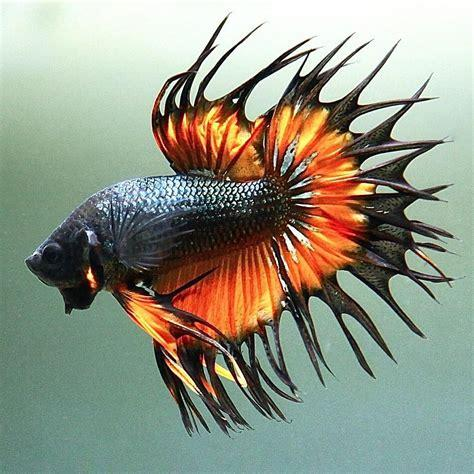

2-- Three Spot Gourami (*Trichopodus trichopterus*) 

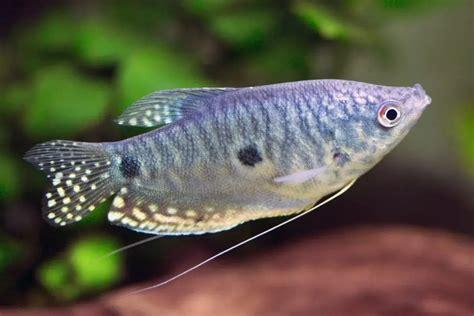

3-- Red-tailed Black Shark (*Epalzeorhynchos bicolor*)

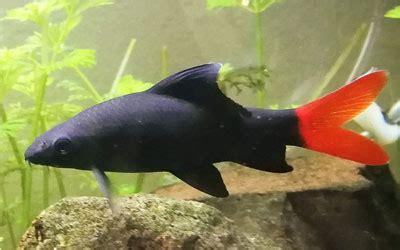

4-- Tiger Barb (*Puntigrus tetrazona*)

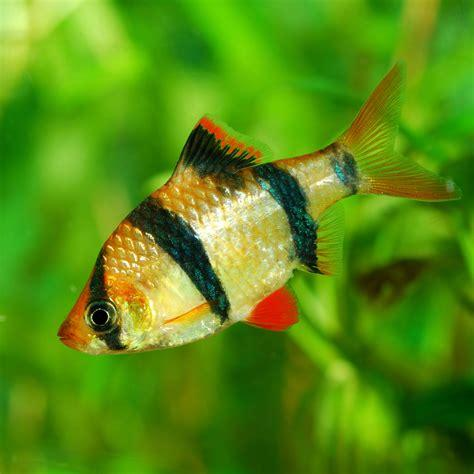

% detect all .jpeg image files in directory
all_jpeg_images = {};
all_jpeg_images = dir("*.jpeg");
% extract full and partial .jpeg image names
images_full_names = {};    % with .jpeg tail
images_partial_names = {}; % without .jpeg tail
for i = 1:length(all_jpeg_images)
    images_full_names{end+1} = all_jpeg_images(i).name;
    images_partial_names{end+1} = erase(all_jpeg_images(i).name, ".jpeg");
end
% convert full and partial .jpeg image names from character vectors to strings
images_full_names_strings = convertCharsToStrings(images_full_names);
images_partial_names_strings = convertCharsToStrings(images_partial_names);
% read images into memory
images ={};
for i = 1:length(images_full_names_strings)
    % capture images after converting image names from character vectors to strings
    images{i} = imread(images_full_names_strings{i});
    % images{i} = imread(convertCharsToStrings(images_full_names_strings{i}))
end

**SECTION 2: TASK B. DISPLAY THE IMAGES                    ****TABLE OF CONTENTS**

The four original images before transformation will be displayed

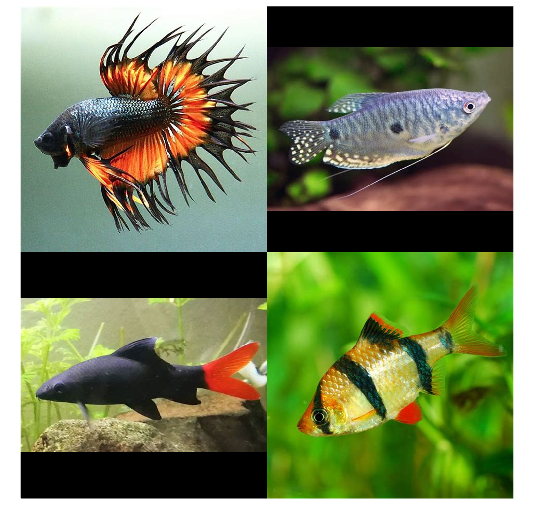

% display montage of images
montage(images)

**SECTION 3: TASK C. APPLY AN IMAGE PROCESSING FILTER/EFFECT OF YOUR CHOICE TO THE IMAGES.                ****TABLE OF CONTENTS**

For each original image, 6 new transformed or processed versions will be created:

1-- Original image version (size: 300 x 300)

2-- Original image version rotated 30 degrees counterclockwise (size: 300 x 300)

3-- Original image version rotated 30 degrees clockwise  (size: 300 x 300)

4-- Horizontally flipped version (size: 300 x 300)

5-- Horizontally flipped version rotated 30 degrees counterclockwise (size: 300 x 300)

6-- Horizontally flipped version rotated 30 degrees clockwise (size: 300 x 300)

The six new versions, all of size 300 x 300, will be assigned new names and saved/exported as .png files to an output folder

% empty array to hold all transformed images
transformed_image_sets = {{}};
% use function "image_transformer" to generate transformed image versions
for i = 1:length(images_full_names_strings)
    transformed_image_sets{i} = image_transformer(images{i});
end

**SECTION 4: TASK D. DISPLAY THE RESULTS                   ****TABLE OF CONTENTS**

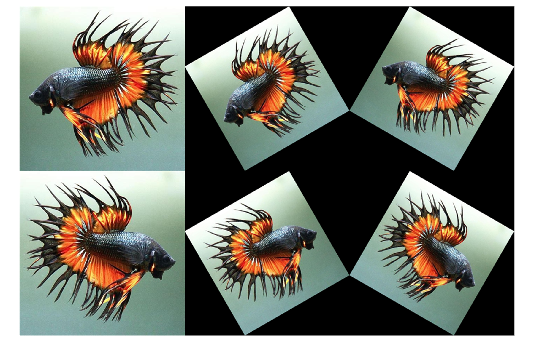

% display transformed processed images
montage(transformed_image_sets{1})

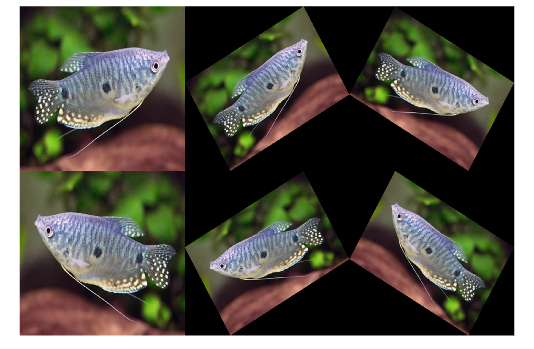

montage(transformed_image_sets{2})

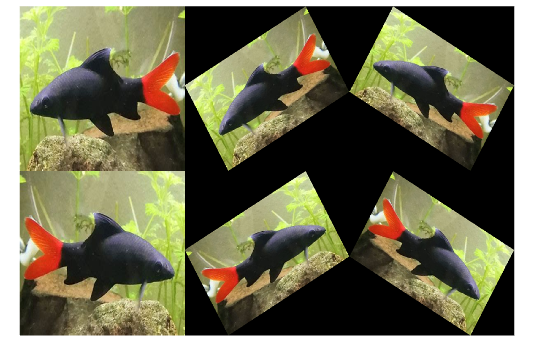

montage(transformed_image_sets{3})

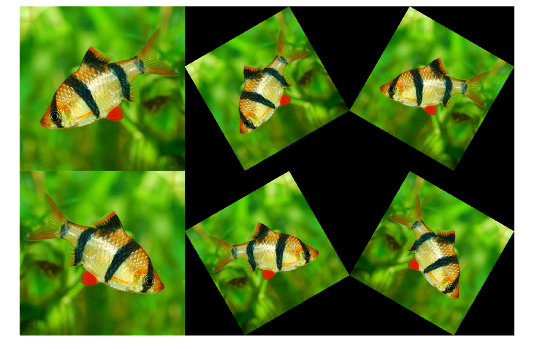

montage(transformed_image_sets{4})

**SECTION 5: TASK E. SAVE THE RESULTING IMAGES TO .PNG FILE FORMAT                   ****TABLE OF CONTENTS**

% loop for each species
for species = 1:length(images_partial_names_strings) 
    species_name = images_partial_names_strings{species}
    % loop for each image in each species' image set
    for pic_num = 1:length(transformed_image_sets{species}) 
       imwrite(transformed_image_sets{species}{pic_num},sprintf("./Output_Images/%s_%d.png",species_name,pic_num))
    end
end

species_name = 'betta'

species_name = 'gourami'

species_name = 'redtail_shark'

species_name = 'tiger_barb'

**SECTION 6: FUNCTIONS                   ****TABLE OF CONTENTS**

Function to perform image transformations 

function [transformed_array] = image_transformer(base_image)
    transformed_array = {};
    transformed_array{1} = imresize(base_image,[300 300]);
    transformed_array{2} = imresize(imrotate(base_image,30),[300 300]); 
    transformed_array{3} = imresize(imrotate(base_image,-30),[300 300]); 
    transformed_array{4} = imresize(flip(base_image,2),[300 300]); 
    transformed_array{5} = imresize(imrotate(flip(base_image,2),30),[300 300]); 
    transformed_array{6} = imresize(imrotate(flip(base_image,2),-30),[300 300]); 
end

**SECTION 7: REFERENCES                    ****TABLE OF CONTENTS**

[https://www.mathworks.com/help/index.html](https://www.mathworks.com/help/index.html)